# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Obtain SAR Data

[https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf](https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf)

## **Pre-Process SAR Data**

Open CosmoSkyMED image in SNAP:

- Subset image

- Save as .nc file

****TO DO:** Remove the need for this step

## 1 Import the CosmoSkyMED Data

### 1.1 Import from file

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/MSc/subset_CSKS1_DGM_B_WR_01_VV_RA_SF_20220722070221_20220722070237_small.nc";

ncInfo_SAR = ncinfo(filepath);
% Create a cosmo satellite object to store all important information.
cosmo = CosmoSkyMED(filepath,"CSK");

% Import general SAR parameters.
sar_scene_orientation_angle = cosmo.SceneOrientationAngle; % Angle offset of the SAR image to North
% IN Sentinel this is called the "centre_heading" and "centre_heading2"

sar_look_metadata = cosmo.LookDirection;
sar_azimuth_to_north_angle = cosmo.azimuthToNorthAngleConversion;
sar_dy = cosmo.AzimuthResolution;
sar_dx = cosmo.RangeResolution;
sar_start_datetime = cosmo.AcquisitionStartDatetime;
sar_stop_datetime = cosmo.AcquisitionStopDatetime;

% Import the SAR data.
sar_latGrid = ncread(cosmo.Filepath,'lat')';
sar_lonGrid = ncread(cosmo.Filepath,'lon')';
sar_Data_uncalibrated = (cosmo.getSARImage)';
% sar_Data_uncalibrated = sar_Data_uncalibrated/mean(sar_Data_uncalibrated(:)); % Normalise the intensity values to a value between 0 and 1.





Alternatively, import the data as an hdf5 file.

% filepath = "/Users/tris/Documents/MATLAB/MSc/20220722_1778608_CSG_/CSG_SSAR1_DGM_B_0301_SC1_001_VV_RA_F_20220722065043_20220722065057_1_F_57S_Z31_N00.h5";
%
% h5Info = h5info(filepath);
%
% % Create a structure to store imported HDF5 data
% sarData = h5read(filepath, '/IMG');
% % Display results
% figure; imshow(sarData);

### 1.2 View Original SAR Data

Choose whether to display a image of the imported SAR data.

% plotSARData = true;
% figure;
% pcolor(sar_Data_uncalibrated.^2);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) No Cal SAR image - 22/07/2022")
% ylabel("Across Range Pixels");
% xlabel("Along Range Pixels");

### 1.3 Radiometric Calibration

sar_Data = cosmo.radiometricCalibration(sar_Data_uncalibrated);
sar_Data = sar_Data/mean(sar_Data(:)); % Normalise the intensity values to a value between 0 and 1.


% plotSARData = true;
% figure;
% pcolor(sar_Data.^2);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
% ylabel("Across Range Pixels");
% xlabel("Along Range Pixels");

% figure;
% pcolor(sar_lonGrid,sar_latGrid,sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
% ylabel("Latitude");
% xlabel("Longitude");

% figure;
% pcolor(sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);

Clear vars

clear sar_Data_uncalibrated;

## 2 Open Ocean Transect

This transect needs to be absent of any ice i.e. completely open ocean.

****TO DO**: Come up with a smart way of doing open ocean detection when selecting the first transect. 

sar_transect_size = 512; % This is the standard size used.
sar_sub_transect_size = 128;

### **2.1 Define Points of Interest / Transect**

These are the top left corner point of the OO transect.

latitude_of_interest = -58.59;
longitude_of_interest = -1.1;

### 2.2 Create the OO Transect

Now we need to find the indexes. Note that in matlab dimension are row by columns = y by x = latitude by longitude

sar_transect_lat_start_index = find(floor(sar_latGrid(:,1)*100)/100 == latitude_of_interest);
sar_transect_lat_end_index = sar_transect_lat_start_index - sar_transect_size +1;

sar_transect_lon_start_index = find(floor(sar_lonGrid(sar_transect_lat_start_index(1),:)*100)/100==longitude_of_interest);
sar_transect_lon_end_index = sar_transect_lon_start_index + sar_transect_size -1;

sar_transect = sar_Data(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_lonGrid = sar_lonGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_latGrid = sar_latGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
% 
% % Plot the transect on the original image
% figure;
% pcolor(sar_lonGrid, sar_latGrid, sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% hold on;
% pcolor(sar_transect_lonGrid,sar_transect_latGrid,sar_transect);
% hold off;

% % Plot the transect
% figure;
% pcolor(sar_transect_lonGrid, sar_transect_latGrid, sar_transect);
% shading("flat");
% colormap("gray");
% clim([0 2]);

### 2.3 Update the latitudes and longitudes

start_latitude= sar_transect_latGrid(1,1);
stop_latitude= sar_transect_latGrid(sar_transect_size,sar_transect_size);
start_longitude = sar_transect_lonGrid(1,1);
stop_longitude = sar_transect_lonGrid(sar_transect_size,sar_transect_size);

Clear variables

clear sar_latGrid; clear sar_lonGrid; clear sar_Data;

## 3 ERA5 Data

This is wave model data. We need to subdivide it to get the matching time, date, lattitudes and longitudes of our SAR data. The larger data then also needs to be sliced so that we can get the data matching the OO transect.

Finally, we need to calculate or use the mean wave direction so that are able to subdivide the SAR image into transects that flow into the ice.

### 3.1 Download

Get this from the CDS_ERA5_datahandling.mlx script. ****TO DO**: Make it adjustable so that the correct date and time data can be downloaded.

### 3.2 Import the data from the file

The data needs to be 'decoded' according to the ERA5 documentation:  [https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation](https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation)

Specifically:

"

The NetCDF wave spectra file will have the dimensions longitude, latitude, direction, frequency and time.

However, the direction and frequency bins are simply given as 1 to 24 and 1 to 30, respectively.

The **direction bins** start at 7.5 degree and increase by 15 degrees until 352.5, with 90 degree being towards the east (Oceanographic convention).

The **frequency bins** are non-linearly spaced. The first bin is 0.03453 Hz and the following bins are: f(n) = f(n-1)*1.1; n=2,30. 

The data provided is the log10 of spectra density. To obtain the spectral density one has to take to the power 10 (10 ** data). This will give the units 2D wave spectra as m**2 s radian**-1 . Very small values are discarded and set as missing values. These are essentially 0 m**2 s radian**-1.

This recoding can be done with the Python [xarray](http://xarray.pydata.org/en/stable/) package, for example:

**Units of 2D wave spectra**

Once decoded, the units of 2D wave spectra are m2 s radian-1

"

%% Get Parameters of the complete
filepath = "/Users/tris/Documents/MSc/ice-SAR-pipeline/software/SCALE_ERA5-2Dws_20220722.nc";

% Store file info in MATLAB struct
ncinfo_era5 = ncinfo(filepath);

era5 = ERA5(filepath);

% Get attributes
era5_lon = era5.getLongitude;
era5_lat = era5.getLatitude;
era5_time = era5.getTime;
era5_d2fd_all_5dims = era5.getAllWaveSpectrumD2FD; 

era5_freq_bins = era5.FrequencyBins;

era5_direction_bins_original = era5.DirectionBins;

We need to then adjust the wave spectrum so that it is oriented the same as the SAR scene orientation

% We need to rotate the wave spectrum so that it is aligned with the angle
% at which the SAR data has been taken.
era5_direction_bins = era5.getDirectionsInSARGeometry(sar_azimuth_to_north_angle);

### **3.3 Get the Wave spectrum at similar points to SAR data**

#### **3.3.1 Find the longitude and latitudes that are the closest to the SAR transect**

****TO DO: Need to figure out how to find the matching lat and long positions (round, floor or ceil? based on the first or last pixel location?) - future me: based on center I think since this is how we calc incidence angle, slant range and transects.**

****TO DO: ADD evaluation for spectrum selected (if the closest point in the lat lon match is in the ice then check the next option).**

clear era5_d2fd;
era5_d2fd = era5.getSlicedWaveSpectrumD2Fd(start_latitude,start_longitude,sar_start_datetime);
clear era5_d2fd_all_5dims;

### **3.4 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

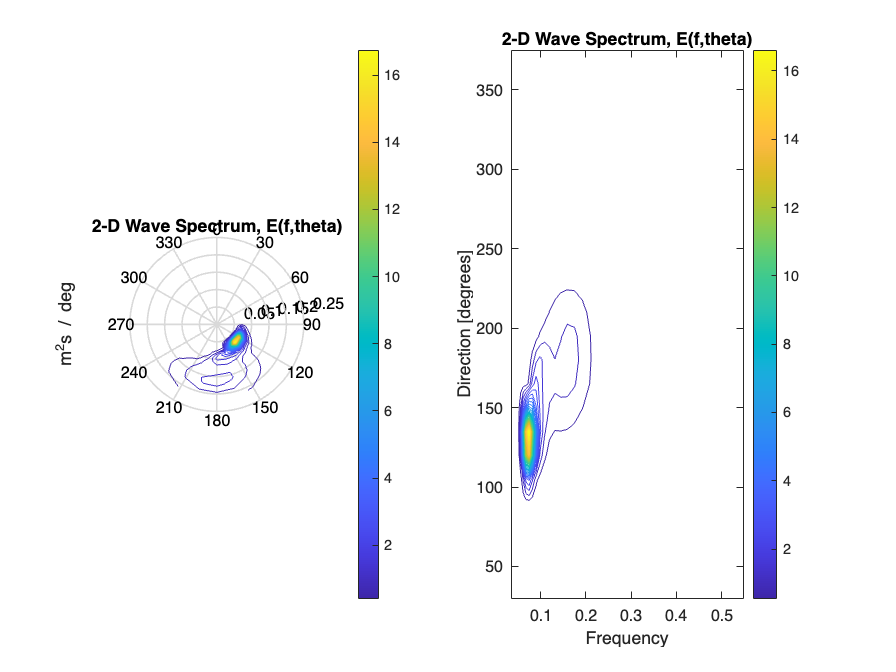

plotERA52Dspectrum = true;
if plotERA52Dspectrum
    % Plot the 2D spectra
    figure;
    subplot(1,2,1);
    PolarContour(era5_d2fd, era5_freq_bins, 0.23, era5_direction_bins, 40); % ADD AZ AND RANGE AXIS LABELS
    title("2-D Wave Spectrum, E(f,theta)")
    % TO DO: Reformat to  -> 360 and add lines for every 30 degrees
    subplot(1,2,2);
    contour(era5_freq_bins,era5_direction_bins,era5_d2fd,30);
    xlabel("Frequency"); ylabel('Direction [degrees]');title("2-D Wave Spectrum, E(f,theta)"); colorbar;
end

# Open Ocean H&H

## 1 First guess wave number spectrum

*This is derived from the Directional Wave Buoy (ERA5) Wave Spectrum data.*

- *You need to orient the wave spectrum to the SAR image angle. The SAR image is taken at a certain angle to the North (this angle can be found in the metadata). The ERA wave spectrum needs to be rotated so that it is inline with this. This is done earlier in the code when the data is imported by adding this angle to the direction bins of the ERA5 data. THis is a very important sstep as you need to orient the real spatial data in temrs of the SAR geometry. This angle can also clearly be seen when viewing the SAR image plots (the plot where the longitude and latittude axes are added vs the plot where they are not).*

- *Then we need to calculate the ****wave number spectrum**** from the E(f, theta). Note here that the ERA data is given in E(f,theta) but the Holthuijsen formula requires E(w,theta). To obtain this we need E(w, theta) = 2 pi E(f, theta). Holthuijsen is used as the reference for this BUT also investigate the Dynamics and Modeling of Ocean Waves (recommended by Giacomo).*

- **Note: The wave number spectrum is the projection of the wave spectrum (f,theta) into the wavenumber (kx,ky) domain.** **"**Where the wave spectrum considers the sea as a function of space and time, η(x, y, t), the ocean can also be considered as a function of space at a single moment in time. This idea is useful for remote sensing applications."  "The wave-number spectrum, E(kx,ky) is useful for remote sensing applications, and the frequency-direction spectrum, E(f,θ), is used for wave models"  (Ryan 4022). pg 20-21

- This needs to be a plot of the ERA5 d2fd data on a kx ky grid. See the comments below but need to look at how it is done in Holthuijsen.

- Make the plot and then compare to the HH paper. Plot next to the f theta plot to see the difference and the translation.

### 1.1 Parameter Calculations / Instantiation

gravity = 9.81;

### **1.2 Wave Number Spectrum Function**

**Holthuisen** states that "*"Remote-sensing *and numerical wave models can estimate the full two-dimensional spectrum, usually the wave-number spectrum *E *(*k x *, *k y *)" [pg.52 Holthuijsen]. So we now need to calculate the wave number spectrum

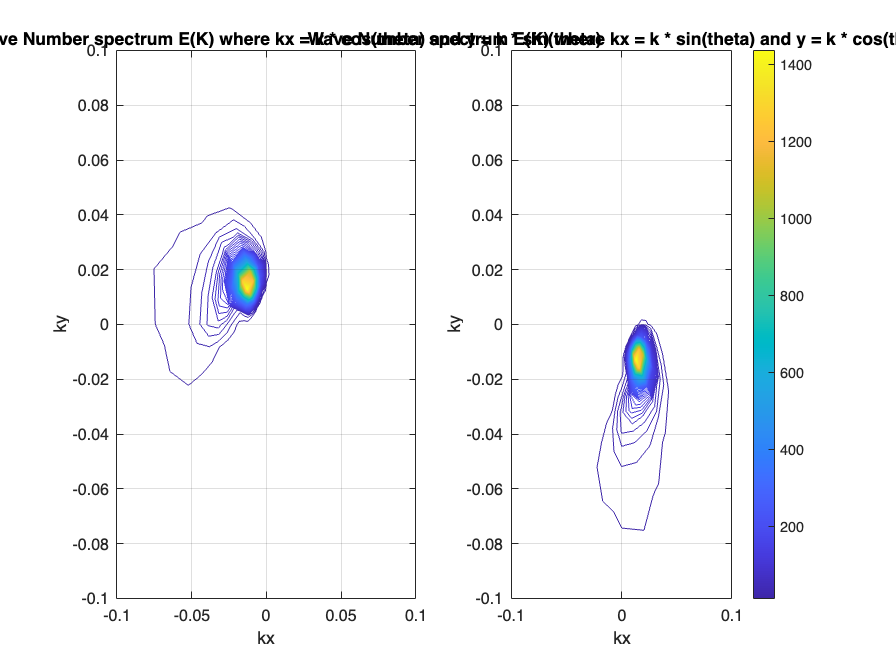

era5_k = (2*pi*era5_freq_bins).^2 ./ gravity; % from deep water approximation of omega = sqrt(gk), [Eq.5.4.18 Holthuijsen]
era5_omega = sqrt(gravity .* era5_k); % era5_omega = 2 * pi * era5_freq_bins; % Angular velocity, omega = 2pi * frequency

era5_d2wd = era5_d2fd ./ (2 * pi); % conver E(f, theta) to E(w, theta)

% This is convention:
era5_kx_matrix_hhdefintion = era5_k .* cosd(era5_direction_bins); % [rad/m] [Eq.3.5.19b Holthuijsen]
era5_ky_matrix_hhdefintion = era5_k .* sind(era5_direction_bins); % [rad/m] [Eq.3.5.19b Holthuijsen]
% From the above equations, and because we want to orient the grid in line
% with the SAR image where the vertical axis (ky) is azimuth and the
% horizontal axis (kx) is range. THIS IS DIFFERENT TO THE CASE OF H&H BUT
% CHANGING THINGS HERE WILL MEAN NO ISSUES GOING FORWARD. IT IS IMPORTANT
% TO NOTE THIS CONVENTION IN THE BEGINNING.
era5_kx_matrix = era5_k .* sind(era5_direction_bins);
era5_ky_matrix = era5_k .* cosd(era5_direction_bins);

% Positive k wave number spectrum E(k)
[era5_E_kx_ky,Jacobian] = waveNumberSpectrum(era5_d2wd,era5_omega,era5_k);

k = sqrt(era5_kx_matrix_hhdefintion.^2 + era5_ky_matrix_hhdefintion.^2);
[era5_E_kx_ky_hhdefinition,Jacobian] = waveNumberSpectrum(era5_d2wd,era5_omega,k);

% CHECK THE PLOTTING DIRECTION COMPARED TO POLAR & OCEANOGRAPHY STANDATDS
figure;
subplot(1,2,1); contour(era5_kx_matrix_hhdefintion, era5_ky_matrix_hhdefintion, era5_E_kx_ky_hhdefinition,100);
xlim([-0.1,0.1]); ylim([-0.1,0.1]);
xlabel("kx"); ylabel("ky"); title("OLD Wave Number spectrum E(K) where kx = k * cos(theta) and y = k * sin(theta)");
grid on;
subplot(1,2,2); contour(era5_kx_matrix, era5_ky_matrix, era5_E_kx_ky,100);
xlim([-0.1,0.1]); ylim([-0.1,0.1]);
xlabel("kx"); ylabel("ky"); title("Wave Number spectrum E(K) where kx = k * sin(theta) and y = k * cos(theta)");
grid on; colorbar;

#### Parameter (E, k , kx & ky) plots

% % My attempt at understanding what is going on:
% figure('Position', [0, 0, 1200, 300]);
% subplot(1,4,1)
% plot(era5_k);
% title("ERA5 k"); xlabel('k bin number'); ylabel('magnitude');
%
% subplot(1,4,2);
% contour(rot90(era5_direction_bins,2),era5_k ,era5_kx_matrix);
% title("ERA5 kx"); xlabel('ERA5 k'); ylabel('Direction [degrees]');
%
% subplot(1,4,3);
% contour(rot90(era5_direction_bins,2), era5_k, era5_ky_matrix);
% title("ERA5 ky"); xlabel('ERA5 k'); ylabel('Direction [degrees]');
%
% subplot(1,4,4); % Positive 2-D wave number spectrum E(kx,ky)=E(k)
% contour(era5_kx_matrix, era5_ky_matrix, era5_E_kx_ky,100);
% xlim([-0.05 0.05]);ylim([-0.08 0.08]);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]'); title("E(k) [m^2 s/rad]");

### 1.3 Plot Wave Number Spectra, E(k) with E(f,theta)

% figure('Position', [200, 200, 1200, 400]);
%
% subplot(1,3,1);
% contour(era5_kx_matrix, era5_ky_matrix, era5_E_kx_ky,100);
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% title({"2-D Wave Number Spectrum"},{"E(k_x,k_y) = E(k) [m^2 s/rad]"});
%
% % subplot(1,3,2);
% % contour(era5_kx_matrix_neg_k, era5_ky_matrix_neg_k, era5_E_kx_ky_neg_k,100);
% % xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% % xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% % title({"Negative 2-D Wave Number Spectrum"}, {"E(-k) [m^2 s/rad]"});
%
% subplot(1,3,2);
% contour(era5_freq_bins,era5_direction_bins .* 180/pi,era5_d2fd',100);
% xlabel("Frequency"); ylabel('Direction [degrees]');title("2-D Wave Spectrum, E(f,theta)")
% % Check that the number spectrum was calculated correctly: we should be
% % able to calculate the original energy from the wave number spectrum.
% isequal(era5_E_kx_ky(5,5)/scaling_factor(5), era5_d2fd(5,5))

### 1.4 First Guess Wave Number Spectra Variables

The original ERA5 data is in a 24x30 grid format, however the SAR transect is 512x512 pixels. For this reason the original ERA5 data is extrapolated into a 512x512 grid.

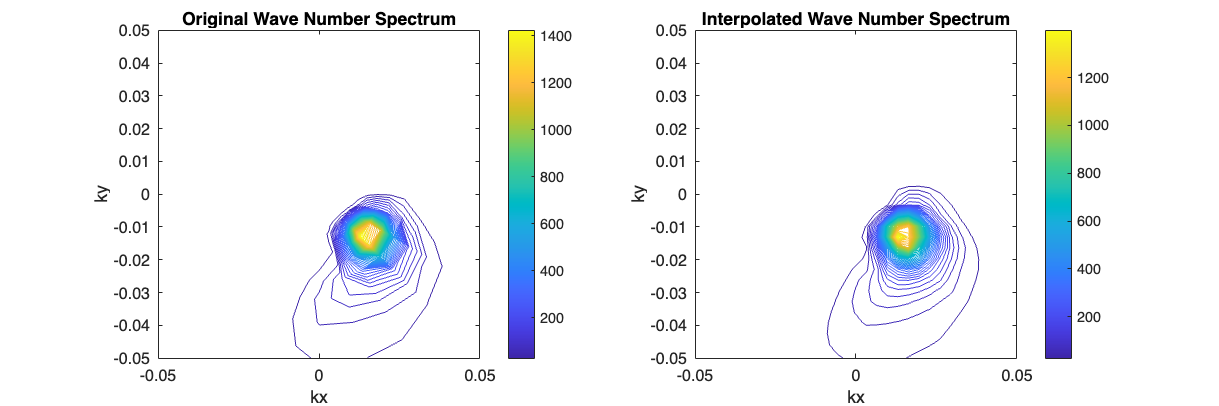

% % Resize the kx and ky matrices.
% extrap_kx = linspace((min(min(abs(era5_kx_matrix)))),(max(max(abs(era5_kx_matrix)))),sar_sub_transect_size/2);
% extrap_kx = [-1*fliplr(extrap_kx) extrap_kx];
extrap_kx = (2*pi/(sar_dx*sar_sub_transect_size)) * ([-1*sar_sub_transect_size/2:1:-1 1:1:sar_sub_transect_size/2]);

extrap_ky = (2*pi/(sar_dy*sar_sub_transect_size)) * ([-1*sar_sub_transect_size/2:1:-1 1:1:sar_sub_transect_size/2]);
% extrap_ky = linspace((min(min(abs(era5_ky_matrix)))),(max(max(abs(era5_ky_matrix)))),sar_sub_transect_size/2);
% extrap_ky = [-1*fliplr(extrap_ky) extrap_ky];

[extrap_kx_matrix, extrap_ky_matrix] = meshgrid(extrap_kx,extrap_ky);
F = scatteredInterpolant(era5_kx_matrix(:) , era5_ky_matrix(:) , era5_E_kx_ky(:), 'natural');
extrap_E_kx_ky = F(extrap_kx_matrix,extrap_ky_matrix);

figure('Position', [200, 200, 1200, 400]);
subplot(1,2,1); contour(era5_kx_matrix,era5_ky_matrix,era5_E_kx_ky,50);
xlim([-0.05 0.05]); ylim([-0.05 0.05]); colorbar;
xlabel("kx"); ylabel("ky"); title("Original Wave Number Spectrum");
subplot(1,2,2); contour(extrap_kx,extrap_ky,extrap_E_kx_ky,50);
xlim([-0.05 0.05]); ylim([-0.05 0.05]); colorbar;
xlabel("kx"); ylabel("ky");title("Interpolated Wave Number Spectrum");

% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));

[temp1, temp2] = find(extrap_E_kx_ky==max(extrap_E_kx_ky(:)));
k0 = first_guess_k(temp1,temp2);
peak_wave_length_Ek = 2*pi/k0;

The code below is a sanity check to understand the effects of the extrapolation on the spectrum. The peak wave period of the original (old) and extrapolated (new) are calculated and compared.

% % Check the quality of the extrapolation (internal sanity check)
% [test_index1_new, test_index2_new] = find(extrap_E_kx_ky==(max(max(extrap_E_kx_ky))));
% test_k_value_new = sqrt(extrap_kx_matrix(test_index1_new, test_index2_new).^2 + extrap_ky_matrix(test_index1_new, test_index2_new).^2);
% test_omega_value_new = sqrt(gravity * test_k_value_new);
% test_period_new = 2*pi/test_omega_value_new
% [test_index1_old, test_index2_old] = find(era5_E_kx_ky==(max(max(era5_E_kx_ky))));
% test_k_value_old = sqrt(era5_kx_matrix(test_index1_old, test_index2_old).^2 + era5_ky_matrix(test_index1_old, test_index2_old).^2);
% test_omega_value_old = sqrt(gravity .* test_k_value_old);
% test_period_old = 2*pi/test_omega_value_old
% % TODO: COMPARE TO THE PEAK WAVE PERIOD

These final variables are redundant but helpful for now in the process of understanding things.

first_guess_wave_number_spectrum = extrap_E_kx_ky;
% first_guess_kx_matrix = extrap_kx_matrix;
% first_guess_ky_matrix = extrap_ky_matrix;
% first_guess_kx = extrap_kx;
% first_guess_ky = extrap_ky';
first_guess_kx = extrap_kx_matrix;
first_guess_ky = extrap_ky_matrix;
% first_guess_k = extrap_k;
first_guess_k = sqrt(first_guess_ky.^2 + first_guess_kx.^2);
% first_guess_omega = extrap_omega;
first_guess_omega = sqrt(gravity .* first_guess_k);

## 2 First Guess SAR Spectrum - H&H's Sar Imaging of Ocean Waves *pg.2*

*This is derived from the First Guess Wave Number Spectrum.*

- Figure our where in the paper this is and then compute the SAR spectrum from the ERA 5 first guess wave spectrum in step 1

- Plot these on kx ky grid - might need to limit the Fmax value as shown in Fig 3 of HH91

### 2.1 SAR Image parameters

% Import the functions
handh = hAndH1991Functions;

Read in SAR metadata values.

% %% Import the SAR metadata attributes
sar_polarisation = cosmo.Polarisation;

% Get the slant range
% sar_slant_range = cosmo.SlantRange;
% TODO: Calculate the slant range
% c = physconst('LightSpeed');
% slant_range_time_grid = ncread(cosmo.Filepath,"slant_range_time");
% sar_slant_range_time_transect = slant_range_time_grid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1)); % center of the transect
% sar_center_slant_range = sar_slant_range_time_transect(sar_transect_size/2,sar_transect_size/2) .* c/2; % c/2 because it is the RTT of the signal from the antenna --> earth --> antenna

% Get the plarform velocity
sar_platform_velocity = cosmo.SatelliteVelocity; %m/s from Giacomo's output file.
% Calculate the platform velocity
% orbital_vectors_metadata = ncinfo(filepath).Groups.Groups(1).Groups(1).Groups;  

% Get the incidence angle at the center of the SAR transect.
incident_angle_grid = ncread(cosmo.Filepath,"incident_angle");
sar_center_incidence_angle_degrees_transect = incident_angle_grid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1)); % center of the transect
sar_center_incidence_angle_degrees = sar_center_incidence_angle_degrees_transect(sar_transect_size/2,sar_transect_size/2);
sar_center_incidence_angle_degrees = sar_center_incidence_angle_degrees * ones(sar_sub_transect_size);


% Get the slant range at the scenter of the SAR transect
c = physconst('LightSpeed');
RTT = c /2;
sar_slant_range_time = ncread(cosmo.Filepath,"slant_range_time") .* 10e-9;
sar_slant_range_time = sar_slant_range_time(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1)); % center of the transect
% sar_slant_range = sar_slant_range_time(sar_transect_size/2,sar_transect_size/2) .* RTT;
sar_slant_range = mean(sar_slant_range_time(:)) .* RTT;

cosmo = cosmo.setSlantRange(sar_slant_range);
% sar_slant_range = sar_slant_range * ones(sar_sub_transect_size);

% sar_slant_range = cosmo.SlantRangeToFirstPixel;
% cosmo = cosmo.setSlantRange(sar_slant_range);

% Run the function
[ps_k_nl, TS_k, xi_sqr] = inversion(2, cosmo,first_guess_kx, first_guess_ky, first_guess_k, first_guess_omega, first_guess_wave_number_spectrum, sar_center_incidence_angle_degrees, sar_sub_transect_size);

### 2.2 Frozen Surface Contribution *pg.3-4 *

*First there are a few missing variables that need to be instantiated.*

% [pg43, Hasselmann, 1990] - "...in all cases as mu = 0.5 1/sec and gamma = 0.
% This is consistent with field and laboratory measurements (cf. Keller and Wright, 1975)"
mu = 0.5;

% k in radar look direction variable
[sar_look,handh_kl] = handh.klUsingSARlook(sar_look_metadata,first_guess_kx);

#### Tilt MTF

The change in incidence angle is due to the change in the slope of the wave face.

**Note: In H&H the variable kl is used which I originally interpreted as ky * -1 or 1 (depending on the look angle) due to the information given at the bottom of page 10,715. However, other sources such as Nonlinear Ocean Dynamics pg 178 Eq.6.35.1, Radar Imaging of Ocean Waves pg 42 Eq.3.45 use kx instead. I am trying to figure out what to do here.**

% Tilt MTF

Tt_k = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees,handh_kl); % [Eq.5, H&H 1991]

#### Hydrodynamic MTF

The interactions between short and long waves, which modulate the energy and wave number of the short, Bragg scattering, ripple waves

**Note: In H&H the variable ky is used. However, other sources such as Nonlinear Ocean Dynamics pg 178 Eq.6.35.2, Radar Imaging of Ocean Waves pg 42 Eq.3.51 use kx and other formulas instead. I am trying to figure out what to do here.**

% Hydrodynamic MTF
Th_k = ( (first_guess_omega - i * mu) ./ (first_guess_omega.^2 + mu^2) ) .* 4.5 .* first_guess_k .* first_guess_omega .* (first_guess_kx.^2 ./ first_guess_k.^2);


#### RAR MTF

% RAR MTF calculation
TR_k = handh.rarMTF(Tt_k,Th_k); % [Eq.4, H&H 1991]


#### **Plots**

The RAR MTF plot should look something like the H&H Figure 3.

% Should look something like in H&H Figure 3
% It looks like H&H plots the RAR function on kx and ky axes but I am not
% sure I am correct about that.

figure('Position', [100, 100, 1000, 300]);
subplot(1,3,1); contour(first_guess_kx, first_guess_ky, abs((Tt_k)));
xlabel("kx"); ylabel("ky");title("Tilt MTF"); colorbar;
subplot(1,3,2); contour(first_guess_kx, first_guess_ky,abs((Th_k)));
xlabel("kx"); ylabel("ky"); title("Hydrodynamic MTF"); colorbar;
subplot(1,3,3); contour(first_guess_kx, first_guess_ky,abs((TR_k)));
xlabel("kx"); ylabel("ky"); title("RAR MTF"); colorbar;

#### **RAR Image Variance Spectrum, PR_k**

% RAR Image Variance Spectrum calculation
PR_k = handh.rarImageVarianceSpectrum(TR_k,first_guess_wave_number_spectrum,rot90(TR_k,2),rot90(first_guess_wave_number_spectrum,2)); % [Eq.13, H&H 1991]

figure('Position', [100, 100, 300, 300]);
contour(first_guess_kx, first_guess_ky, PR_k);
xlabel("kx"); ylabel("ky"); title("RAR Image Variance Spectrum, P^{R}_{k}");
xlim([-0.08 0.08]); ylim([-0.08 0.08]); colorbar;

### 2.3 Motion Effects *pg.4-5*

*Compensation for velocity bunching caused by the orbital velocity of the long waves, which produces a Doppler shift in the received, return signal. *

*"*We consider now the modification of the frozen image induced by the surface motion. This is normally described by two effects: the azimuthal displacement, xi, of the apparent position of the backscattering element in the image plane, and an azimuthal smearing or broadening of the image of the (theoretically infinitesimal) backscattering element" [H&H 1991]

***** TO DO: look at calculating the satellite velocity from the metadata rather than hardcoding? (see Ryan's 4022 comments on the Sentinel data - pg.48)***

#### ***Range Velocity MTF***

**Note: In H&H the variable kl is used. Other sources such as Nonlinear Ocean Dynamics pg 180 Eq.6.38.1, Radar Imaging of Ocean Waves pg 42 Eq.3.51 use kx instead. I am trying to figure out what to do here.**

% Range Velocity MTF
Tv_k = handh.rangeVelocityMTF(first_guess_omega, sar_center_incidence_angle_degrees, handh_kl, first_guess_k); % [Eq.17, H&H 1991]

#### Velocity Bunching MTF

**Note: In H&H the variable kl is used. Other sources such as Nonlinear Ocean Dynamics pg 180 Eq.6.38.1, Radar Imaging of Ocean Waves pg 42 Eq.3.51 use kx instead. I am trying to figure out what to do here.**

% Velocity Bunching MTF
sar_beta = handh.beta(sar_slant_range, sar_platform_velocity); %[Eq.15, H&H 1991]

Tvb_k = -1 .* sar_beta .* first_guess_ky .* Tv_k;% [Eq.24, H&H 1991]
% Tvb_k_tes = -1 .* sar_beta .* first_guess_ky .* first_guess_omega .* (cosd(sar_center_incidence_angle_degrees) - (1i .* sind(sar_center_incidence_angle_degrees) .* handh_kl./first_guess_k)); % [Eq.24, H&H 1991]
% Tvb_k_2 = sar_beta .* (cosd(sar_center_incidence_angle_degrees) - 1i .* sind(sar_center_incidence_angle_degrees) .* era5_kx_matrix./era5_k) .* era5_omega .* era5_ky_matrix; % [Eq.6.77 RIoOW textbook]


#### Net SAR Imaging MTF, TS_k

% Net SAR imaging MTF
TS_k = handh.sarImagingMTF(TR_k, Tvb_k); %[Eq.27, H&H 1991]
% TS_k_2 = handh.sarImagingMTF(TR_k, Tvb_k_2); %[Eq.27, H&H 1991]
% TS_k_full = handh.sarImagingMTF(TR_k_full, Tvb_k_full);

#### **Plots**

% Should look something like in H&H Figure 3
% It looks like H&H plots the Velocity bunching MTF on kx and ky axes but I am not
% sure I am correct about that.

%  I am not sure what axes to plot these on.
figure('Position', [100, 100, 1000, 300]);
subplot(1,3,1); contour(first_guess_kx, first_guess_ky,abs((TR_k)));
xlabel("kx"); ylabel("ky"); title("RAR MTF");
colorbar;
subplot(1,3,2); contour(first_guess_kx, first_guess_ky,abs(((Tvb_k))));
xlabel("kx"); ylabel("ky"); title("Velocity Bunching MTF");
colorbar;
subplot(1,3,3); contour(first_guess_kx, first_guess_ky,abs((TS_k)));
xlabel("kx"); ylabel("ky");title("SAR imaging MTF");
colorbar;

#### SAR Image Variance Spectrum

This is the case in which certain conditions are met such that the SAR image is imaging roughness of the ocean surface linearly – see Radar Imaging of Ocean Waves textbook pg 117 onwards. Nonlinearity is then discussed on page 124.

% QUESTION:
% figure;
% pcolor(abs(TS_k));
% shading("interp"); colorbar;

% figure;
% pcolor(fliplr(flipud(abs(TS_k)))); shading("interp"); colorbar;


PS_k_linear = handh.sarImageVarianceSpectrumLinearMappingTransform(TS_k,first_guess_wave_number_spectrum,rot90(TS_k,2),rot90(first_guess_wave_number_spectrum,2));%[Eq.26, H&H 1991]
% PS_k_linear = handh.sarImageVarianceSpectrumLinearMappingTransform(TS_k,first_guess_wave_number_spectrum,0,0);%[Eq.26, H&H 1991]

figure('Position', [100, 100, 300, 300]);
contour(first_guess_kx, first_guess_ky, PS_k_linear,10);
xlabel("kx"); ylabel("ky"); title("Image Variance Spectrum, P^S_1 ");
% xlim([-0.05 0.05]); ylim([-0.05 0.05]);
colorbar; grid on;

### 2.4 General nonlinear mapping relation *pg.5-6*

*The reasoning for doing this is given in H&H on pg 5 in the paragraph before section 3.*

"To determine the dependence of the SAR image Fourier components IS_k on the wave Fourier components in the general nonlinear case, we first apply a Fourier transform to the basic mapping relation [Eq.20, H&H 1991]... this yields the SAR image variance soectrum PS_k [Eq.30, H&H 1991]"

#### Orbital Velocity Covariance

fv_r = ifft2(first_guess_wave_number_spectrum .* abs(Tv_k).^2); % [Eq.43, H&H 1991]

#### RAR Image Intensity Autocovariance Function

fR_r = 0.5 * ifft2(PR_k); % [Eq.47, H&H 1991]
% fR_r = ifft2(first_guess_wave_number_spectrum.*abs(TR_k).^2); % WE DO NOT KNOW WHY

#### Covariance Function of RAR Image Intensity and Oribital Velocity

fRv_r = 0.5 .* ifft2(first_guess_wave_number_spectrum.*TR_k.*conj(Tv_k) + rot90(first_guess_wave_number_spectrum,2) .* conj(rot90(TR_k,2)) .* rot90(Tv_k,2) ); % [Eq.48, H&H 1991]

#### Mean Square Azimuthal Displacement

xi_sqr = sar_beta.^2 .* fv_r(1,1); % [Eq.44, H&H 1991]

#### Quasi-linear Approximation / Quasilinear Mapping Transform

PS_1 = PS_k_linear; % [Eq.55, H&H 1991]

% Add filter to filter out high frequencies
PS_ql = exp(-1 .* first_guess_ky.^2 .* xi_sqr) .* PS_1; % [Eq.56, H&H 1991]

figure('Position', [100, 100, 300, 300]);
contour(first_guess_kx, first_guess_ky, abs(PS_ql));
xlabel("kx"); ylabel("ky = azimuth"); title("Quasilinear Mapping Transform, P^S_{ql}");
xlim([-0.05 0.05]); ylim([-0.05 0.05]);
grid on; colorbar;

[temp1, temp2] = find(PS_ql==max(PS_ql(:)));
k0_test = first_guess_k(temp1(1),temp2(1));
peak_wave_length_ql = 2*pi/k0_test;

% T = 12; % average From the CDS data - get the real value.
% mean_wave_length = g * T^.2 / (2*pi);

#### Spectral Series Expansion Terms

This section of code has not been written efficiently. It has been written into functions in the handh library but I found it a bit difficult to keep track of everthing there, so for now (whilst we are still developing this implementation of the algorithm) I have written the code as it is below.

Giacomo implementation:

% Initialize variables (assuming they are defined elsewhere in your script)
lin_ord = 20;
fv = fv_r;
frv = fRv_r;
frv_r = rot90(fRv_r,2);
frv_00 = fRv_r(1,1);
dx = sar_dx;
n = sar_sub_transect_size;
n21 = sar_sub_transect_size/2 -1;
cshi = xi_sqr;
kaz = first_guess_ky;
kaz1 = kaz .* sar_beta;
fr = fR_r;

ps_k = 0;       


for l = 2:lin_ord
    % tmp1 calculation
    tmp1 = (fv.^l) / factorial(l);
    tmp1 = ifft2(tmp1, 'symmetric');

    % a1 calculation
    a1 = (kaz1.^(2*l)) .* tmp1;

    % tmp2 calculation
    tmp2 = 1i * (frv - frv_r) .* (fv.^(l-1)) / factorial(l-1);
    tmp2 = ifft2(tmp2, 'symmetric');

    % a2 calculation
    a2 = (kaz1.^(2*l-1)) .* tmp2 + a1;

    % tmp3 calculation
    tmp3 = fr .* (fv.^(l-1)) / factorial(l-1) + ...
        (frv - frv_00) .* (frv_r - frv_00) .* (fv.^(l-2)) / factorial(l-2);
    tmp3 = ifft2(tmp3, 'symmetric');

    % tmp4 calculation
    tmp4 = (kaz1.^(2*l-2)) .* tmp3 + a2;

    % Update ps_k
    ps_k = ps_k + tmp4;
end

% Non-linear spectrum calculation
ps_2 = ps_k .* exp(-cshi * kaz.^2) * (dx / (n* 2*pi))^2; % This factor is for converting from 2pi to spatial domain (dx / (n* 2*pi))^2 it is the FFT and dk term in hHH (SEE NOTES BELOW)
ps_k_nl_2 = (PS_ql + ps_2 );

% Plot all components together
figure('Position', [100, 100, 1000, 300]);
% subplot(1,3,1); contour(first_guess_kx, first_guess_ky, abs(PS_1));
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% xlabel("kx"); ylabel("ky"); title("SAR Spectrum, P^S_1"); colorbar;
% subplot(1,3,1); contour(first_guess_kx, first_guess_ky, abs(PS_ql));
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% xlabel("kx"); ylabel("ky"); title("Quasilinear SAR Spectrum, P^S_ql"); colorbar;
% subplot(1,3,1); 
contour(first_guess_kx, first_guess_ky, abs(ps_k_nl_2));
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("kx"); ylabel("ky"); title("SAR Spectrum, P^S_k"); colorbar;
% TO DO: PLOT ALL PS_1, PS_ql, PS_k altogether.

#### My implementation:  but something is wrong --> need to figure out what and compare.

% n = 2; % non-linearity order term
% PS_temp = zeros(sar_sub_transect_size);

#### SAR Spectrum

% % Using % [Eq.50, H&H 1991]
%
% for nonlinearity =1:n
%     if(n==1)
%         PS_temp = PS_temp + PS_ql;
%     end
%     % Spectral Expansion Term 1
%     PS_n_2n = (2*pi)^(-2) .* (fft2((fv_r.^n)./factorial(n))); % [Eq.51, H&H 1991]
%     % figure; contour(PS_n_2n);
%     % Spectral Expansion Term 2
%     PS_n_2n_minus_1 = (2*pi)^(-2) .* (fft2( 1i .* (fRv_r - rot90(fRv_r,2)) .* fv_r .^(n-1) ./ factorial(n-1) )); % [Eq.52, H&H 1991]
%     % figure; contour(abs(PS_n_2n_minus_1));
%     % Spectral Expansion Term 3
%     if(n==1)
%         factorial_n_minus_2 = 0;
%     else
%         factorial_n_minus_2 = 1./factorial(n-2);
%     end
%     PS_n_2n_minus_2 = (2*pi)^(-2) .* fft2( 1./ factorial(n-1) .* fR_r .* fv_r.^(n-1)  ...
%                                                     + factorial_n_minus_2 .* (fRv_r - fRv_r(1,1)) ...
%                                                     .* (rot90(fRv_r,2) - fRv_r(1,1)) .* fv_r.^(n-2) ...
%                                                      ); % [Eq.53, H&H 1991]
%     % figure; contour(abs(PS_n_2n_minus_2));
%
%     PS_k = zeros(sar_sub_transect_size);
%     for m = (2*nonlinearity-2):2*nonlinearity
%         coefficient = (first_guess_ky .* sar_beta).^m;
%         if m == 2*nonlinearity-2
%             PS_k = coefficient .* PS_n_2n_minus_2;
%         elseif m == 2*nonlinearity-1
%             PS_k = PS_k + coefficient .* PS_n_2n_minus_1;
%         elseif m == 2*nonlinearity
%             PS_k = PS_k + coefficient .* PS_n_2n;
%         end
%     end
%     % figure; contour(abs(PS_k));
%
%     PS_temp = PS_temp + PS_k;
%     % figure; contour(abs(PS_temp));
%
% end
% PS_k_nonlinear = exp(-1 .* first_guess_ky.^2 .* xi_sqr) .* PS_temp;
%
% % Plots
% figure('Position', [100, 100, 300, 300]);
% contour(first_guess_kx, first_guess_ky, abs(PS_k_nonlinear));
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% xlabel("kx"); ylabel("ky"); title("SAR Spectrum, P^S_k"); colorbar;
% TO DO: PLOT ALL PS_1, PS_ql, PS_k altogether.

The term (`dx / (2 * pi * n)).^2 `appears to be adjusting the scale of `imfin` to reflect correct units in the frequency domain. Here’s a closer look at why this specific operation is done:

- **Normalization of Spatial Frequency**:

- When transforming a spatial-domain image (or signal) to the frequency domain using a Fourier Transform, the result is given in terms of spatial frequencies. The factor `dx / (2 * pi * n)` converts the discrete frequency components to match the real spatial frequency scale.

- **Sampling Interval (**`dx`**)**:

- `dx` is the spatial resolution or the distance between adjacent samples in the spatial domain. When you apply the Fourier Transform, this interval affects the spacing of frequency components in the transformed result.

- Including `dx` ensures that the frequency components reflect the actual physical distances between samples, rather than a purely abstract, normalized grid.

- **Normalization Factor** `(2 * pi)`:

- The factor `2 * pi` is included because Fourier transforms often assume angular frequency (`ω = 2 * pi * f`), which uses `2 * pi` to convert between cycles per unit (frequency `f`) and radians per unit (angular frequency `ω`). Including `2 * pi` here ensures the correct scaling between spatial and angular frequency domains.

- **Grid Size (**`n`**)**:

- Dividing by `n` accounts for the number of points in the grid. If you are using a grid of `n x n` points, then dividing by `n` normalizes each frequency component by the total number of samples.

- This makes sure the frequency components represent values per unit length in the transformed space, not just abstract FFT indices.

- **Squaring the Term**: `((dx / (2 * pi * n))^2)`

- This term is squared, meaning that the entire scaling factor is applied in both dimensions (since you are dealing with a 2D frequency transformation).

- It is common in 2D FFT scaling to square factors to preserve energy and power relationships across dimensions.

**Why This Scaling Matters**

In summary, `dx / (2 * pi * n)` aligns the frequency-domain data with the real physical units of the original spatial data. Without this scaling, the frequency components in `imfin` would only represent abstract units tied to the FFT index grid, making it harder to interpret results in terms of actual spatial frequencies.

## 3 Observed SAR spectrum

- Subdivide the 512x512 transect into 16 128x128 sub transects

- For each sub transect: filter, normalise, fft

- Take the average of these sub transects

- Need to filter out the low frequencies using butterworth filter applied to covariance function and then ifft back to the spectrum

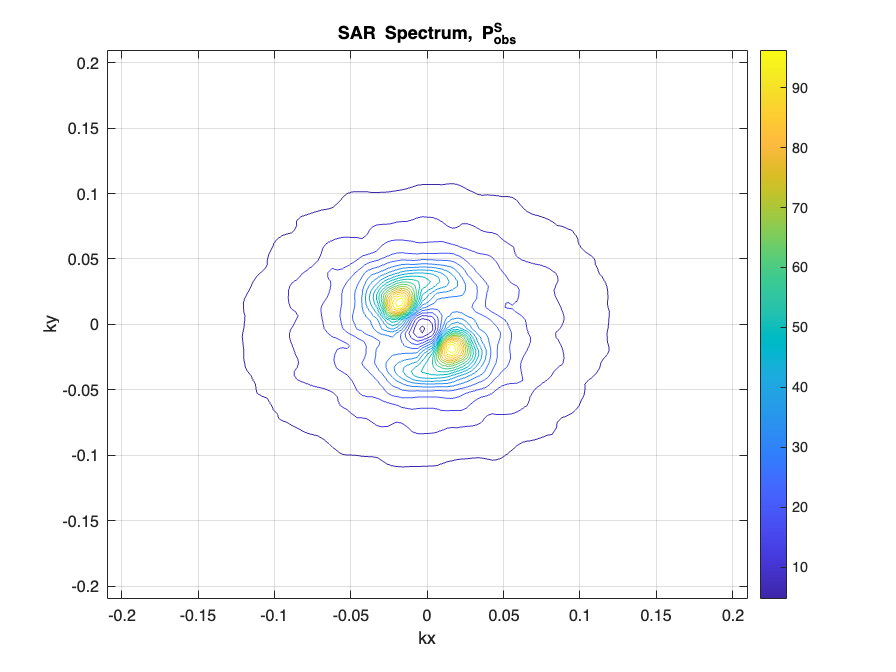

function [cross_spec] = calcola_cross_spettro_WELCH(img1, img2, n, dx, dim_filt, width, kx, ky)

    n21 = n / 2 + 1;
    s = 2 * pi / (n * dx);
    tmp = -pi / dx + (0:n) * s;
    % kx = tmp(2:n+1);
    % ky = kx;
    
    

    % % Calculate the backscatter coefficient
    % sigma0 = mean(img1(:));
    % dev_sigma0 = std(img1(:));
    % fprintf('sigma0 = %.2f [dB]\n', 10 * log10(sigma0));
    % fprintf('dev sigma0 = %.2f [dB]\n', 10 * (dev_sigma0 / sigma0) / log(10));
    % 
    
    scale = 512 / n;
    
 
    
    % Define the Hamming window
    w = hamming(n) * hamming(n)';
    
    imfin = zeros(n, n);
    for i = 1:4
        for j = 1:4
            
            image1 = w .* double(img1((i-1)*128+1:i*128, (j-1)*128+1:j*128));
            image2 = w .* double(img2((i-1)*128+1:i*128, (j-1)*128+1:j*128));
            ave1 = mean(image1(:));
            ave2 = mean(image2(:));
            image1 = image1 / ave1 - 1; % -1 to remove the new average which = 1 
            image2 = image2 / ave2 - 1;
            % image = (fft2(image1) ) .* conj(fft2(image2));
            image = abs(fft2(image1)).^2; % Standard procedure (find in literature)
            image = fftshift(image);
            imfin = imfin + image;
        end
    end
    % imfin = ((dx / (2 * pi * n))^2) * imfin / (2 * scale - 1)^2;
    imfin = (dx / (2 * pi * n))^2 * imfin; 
    imfin = imfin / (scale)^2;
    % imfin = imfin/16;
    
    % % Estimate the raw cross-covariance function
    % cross_var_RAW = fftshift(ifft2(fftshift(imfin)));
    
    

    % Butterworth band-pass filter
    % [kr, ka] = meshgrid(kx, ky);
    kr = kx;
    ka = ky;
    k = sqrt(kr.^2 + ka.^2);
    k(k == 0) = 1e-7;
    cutoff = 500; % This is dependent on the sea state and used to remove the low frequencies. Maybe see if 2 * swell will work.
    k0 = 2 * pi / cutoff;
    butterworth = 1 ./ (1 + (k0 ./ k).^20);
    cross_spec = butterworth .* imfin;

    % Smoothing with a Gaussian filter
    in = dim_filt;
    x = (1:in) - (in) / 2;
    [nn, mm] = meshgrid(x, x);
    k_filt = exp(-(nn.^2 + mm.^2) / width^2);
    k_filt = k_filt/sum(k_filt(:));
    cross_spec = conv2(cross_spec, k_filt, 'same');
    
    % % Estimate the smoothed cross-covariance function
    % cross_var_SMOOTHED = fftshift(ifft2(fftshift(cross_spec)));
end

dim_filt =6;
width = 3;

[cross_spec] = calcola_cross_spettro_WELCH(sar_transect, sar_transect, sar_sub_transect_size, sar_dx, dim_filt, width, first_guess_kx, first_guess_ky);

figure; contour(first_guess_kx, first_guess_ky, abs(cross_spec),20);
xlabel("kx"); ylabel("ky"); title("SAR Spectrum, P^S_{obs}");
colorbar;
grid on;


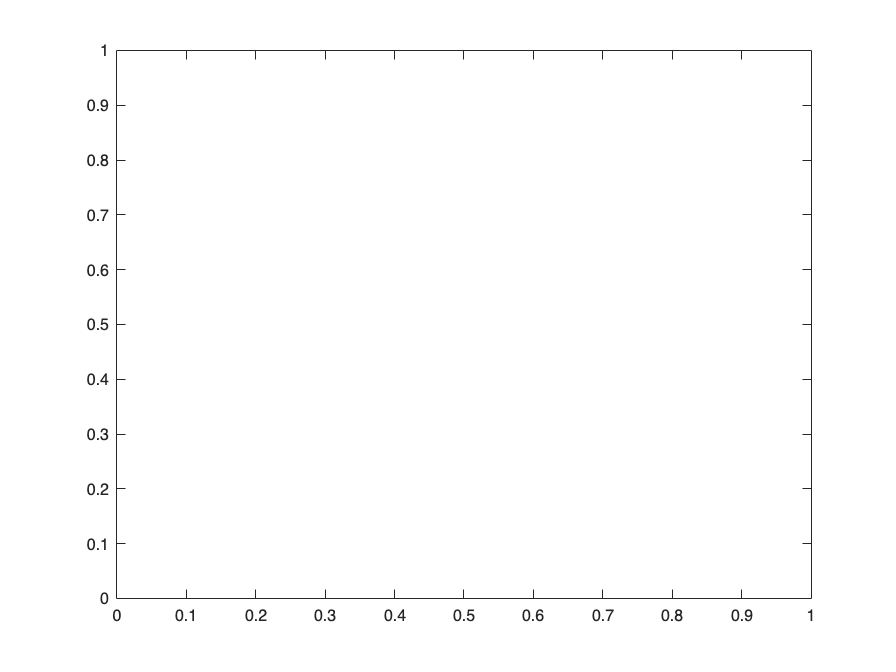

% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));

[temp1, temp2] = find(cross_spec==max(cross_spec(:)));
k0 = first_guess_k(temp1,temp2);
peak_wave_length_sar = 2*pi/k0;

% T = 12; % average From the CDS data - get the real value.

% mean_wave_length = g * T^.2 / (2*pi);

modk = first_guess_k;
anello  = 1 - 1./(1+(k0./modk).^5); % MIGHT NEED TO ADJUST POWER (5 in this case) FOR DIFFERENT CASES


## 4 Inversion

- "Step zero" as Giacomo calls it

P_obs = cross_spec ;
kx = first_guess_kx(1,:);
ky = first_guess_ky(:,1);

[temp1, temp2] = find(P_obs==max(P_obs(:)));
k0 = first_guess_k(temp1,temp2);
modk = first_guess_k;
anello  = 1 - 1./(1+(k0./modk).^7); % MIGHT NEED TO ADJUST POWER (5 in this case) FOR DIFFERENT CASES


J_GUESS   = 1e+10;

% EPS_GUESS = 1.e+10;
rot = -30:1:30;
mag = 0.3:0.1:2;
J_new = zeros(length(rot),length(mag) );
for i_rot = 1:length(rot)
    for i_mag = 1:length(mag)
        for x_shift = -3:1:3
            for y_shift = -5:1:5
                
                A = circshift(first_guess_wave_number_spectrum, [y_shift x_shift]);

                % S_tmp = i_energy*rot(S_2D_buoy, i_rot, i_mag, /interp)
                S_tmp = mag(i_mag) * imrotate(A, rot(i_rot), 'bilinear', 'crop');
    
                % find(isnan(S_tmp))
                 %     forward_insieme_range, lin_ord, beta1, look_sep, S_tmp, P_tmp, TMP, cshi, fv_00, rg_res
                %     P_tmp = double(P_tmp)
                %     sub = where(P_tmp lt 0d)
                %     if sub[0] ne -1l then P_tmp[sub] = 0d
                 %     P_tmp = P_tmp*BUTTERWORTH
                P_tmp = inversion(2, cosmo,first_guess_kx, first_guess_ky, first_guess_k, first_guess_omega, S_tmp, sar_center_incidence_angle_degrees, sar_sub_transect_size);
    
    
                J_new(i_rot,i_mag) = trapz(kx, trapz(ky, (P_tmp - P_obs).^2 .* anello ,1),2) ./ sqrt(trapz(kx, trapz(ky, (P_obs).^2 .* anello ,1),2)) ./ sqrt(trapz(kx, trapz(ky, (P_tmp).^2 .* anello ,1),2));
    
    
                if J_new(i_rot,i_mag) < J_GUESS
                    J_GUESS    = J_new(i_rot,i_mag);
                    S_new      = S_tmp;
                    P_new      = P_tmp;
                    x_shift0   = x_shift;
                    y_shift0= y_shift;
                    mag_0       = mag(i_mag);
                    rot_angle_0  = rot(i_rot);
    
                end
            end
        end

    end
end

% figure; pcolor(mag,rot,J_new)

function [S_OUT, P_OUT,J] = inverti_sea_HH91_MIO(S_INP, P_obs1, P_guess, TS_k, first_guess_ky,first_guess_kx,xi_sqr, first_guess_omega,cosmo,sar_look_metadata,first_guess_k,sar_center_incidence_angle_degrees, sar_sub_transect_size)
    % INPUTS:
    % S_INP  --> input first guess ocean wave spectrum
    % rg_res --> range resolution
    %
    % OUTPUTS:
    % S_OUT --> output best fit ocean wave spectrum
    % P_OUT --> SAR spectrum corresponding to S_BEST
    
    % % Define constants and parameters
    % grav = 9.81; % acceleration due to gravity
    % k0 = 2 * pi / lc_obs;
    % anello = 1 - 1 / (1 + (k0 / modk)^5);
    % k0 = 2 * pi / 500;
    % butterworth = 1 / (1 + (k0 / modk)^20);
    % beta_ = beta1; % =R/V -> slant range OVER platform velocity
    % 
    % % First guess directional wave spectrum
    % S_guess = S_INP;
    % S0 = S_guess;
    % P_obs = P_obs1;
    % teta = teta1; % incidence angle at the center of image tile [rad]
    % i = 1i;
    % t = look_sep; % time interval between two looks in SAR cross spectra
    % n = nn; % size along each direction
    % dx = ddx; % pixel size in meters
    % lin_ord = lin_ord; % non linearity order in generating the simulated SAR image spectrum
    % 
    % % Load SAR imaging parameters
    % Ti = load('Ti.dat');
    % Ty = load('Ty.dat');
    % Ts_k = Ti - i * beta_ * kaz * Ty;
    % n21 = floor(n / 2) - 1;
    % xx = conj(Ts_k);
    % tmp = circshift(xx, [-n21, -n21]);
    % Ts_k_meno = fft2(tmp) / (n^2);
    % Ts_k_meno = circshift(Ts_k_meno, [n21 + 1, n21 + 1]);
    % 
    % % Initialize variables
    % S_ice = S_guess;
    % mu0 = 1e-1 * max(P_obs)^2;
    % B = 1e-2 * max(S_guess);
    % 
    % % Forward model
    % [P_guess, P_nl, cshi] = forward_insieme_range(lin_ord, beta_, look_sep, S_guess, rg_res);
    % P_guess = P_guess * butterworth;
   
    % J_guess = int_tabulated_2d(kx, ky, anello * P_obs .* (P_obs - P_guess).^2) + ...
    %     mu0 * int_tabulated_2d(kx, ky, anello * (S_ice - S_guess).^2 ./ (B + S_guess).^2);
    
    % k0 = 2 * pi / lc_obs;
    % anello = 1 - 1 / (1 + (k0 / modk)^5);

    P_obs = P_obs1;
    
    % Ring
    [temp1, temp2] = find(P_obs==max(P_obs(:)));
    k0 = first_guess_k(temp1,temp2);
    modk = first_guess_k;
    anello  = 1 - 1./(1+(k0./modk).^5); % MIGHT NEED TO ADJUST POWER (5 in this case) FOR DIFFERENT CASES
    
    % Butterworth
    % butterworth  = 1 - 1./(1+(k0./modk).^20); 
    butterworth =  1 - 1./(1+(k0./(2*modk))^20);% Removing all the contributions from waves 2 x peak wave length 

    kx = first_guess_kx(1,:);
    ky = first_guess_ky(:,1);
    
    kaz = first_guess_ky;
    cshi = xi_sqr;
    n = 128;
    omega = first_guess_omega;
    % t = look_sep; % time interval between two looks in SAR cross spectra
    t=0;

    S_guess = S_INP;
    S0 = S_guess;
    
    P_ice = P_obs;


    S_ice = S_guess;


    B = 1e-2 * max(S_guess);
    mu0 = 1e-1 * max(P_obs(:)).^2;
    mu = mu0; % assumption in H&H

    term1 = (P_guess - P_obs).^2 .*  P_obs .* anello;
    term2 = anello .* ( (S_ice - S_guess) ./ (B + S_guess) ).^2;
    
    J_guess_0 = trapz(kx, trapz(ky, term1,1),2) + trapz(kx, trapz(ky, mu .* term2,1),2); % MAYBE just check this trapz()
    % J_guess = trapz(kx, trapz(ky, term1,1),2); % MAYBE just check this trapz()
    
    eps_guess = trapz(kx, trapz(ky, (P_guess - P_obs).^2 .* anello ,1),2) ./ sqrt(trapz(kx, trapz(ky, (P_obs).^2 .* anello ,1),2)) ./ sqrt(trapz(kx, trapz(ky, (P_guess).^2 .* anello ,1),2));
    eps_guess0 = eps_guess;
    eps(1) = eps_guess;

    P_ice = P_guess;
    
    J(1) = J_guess_0;
    Jmax = J(1);

    S_best = 0;
    P_best =0;

    % Iterative inversion
    for iterazione = 1:20
        B = 1e-2 * max(S_guess);
        
        mu_k = mu0 ./ (B + S_guess).^2;
        mu_k = mu_k .* anello;
        mu_k_minus = rot90(mu_k,2);

        % PLOT mu_k IT IS THE FILTER!!!!
        
        % tmp = circshift(mu_k, [-n21, -n21]);
        % tmp = rot90(mu_k,2);
        % mu_k_minus= fft2(tmp) / (n^2);
        % mu_k_minus = circshift(mu_k_meno, [n21 + 1, n21 + 1]);
        % mu_k_minus = rot90(mu_k,2);

        % W_k = 0.5 * abs(Ts_k).^2 .* exp(-kaz.^2 * cshi) .* cos(omega * t);
         % % tmp = circshift(W_k, [-n21, -n21]);
        % W_k_meno = fft2(tmp) / (n^2);
        % W_k_meno = circshift(W_k_meno, [n21 + 1, n21 + 1]);
        W_k = abs(TS_k).^2 .* exp(-kaz.^2 * cshi) .* cos(omega); % [Eq. 75, H&H 1991]
        W_k_minus = rot90(W_k,2); 
        W_k_minus = W_k_minus.*anello;
        W_k = W_k.*anello;
        
        
        % A_k = P_obs .* W_k.^2 + mu_k;
        % tmp = circshift(A_k, [-n21, -n21]);
        % A_k_meno = fft2(tmp) / (n^2);
        % A_k_meno = circshift(A_k_meno, [n21 + 1, n21 + 1]);
        A_k = P_obs .* W_k.^2 +mu_k;
        A_k_minus = rot90(A_k,2);
        A_k = A_k .* anello;
        A_k_minus = A_k_minus .* anello;

        % A_k = W_k.^2 + 2 * mu0; % [Eq. 73, H&H 1991]
        % A_k_minus = rot90(A_k,2); 

        
        B_k = P_obs .* W_k .* W_k_minus .* anello;
        % B_k = W_k .* W_k_minus .* anello;  % [Eq. 74, H&H 1991]
        
        % dP_k = (P_obs - P_ice) .* anello; 
        dP_k = (P_obs - P_ice) .* anello; % [Eq. 71, H&H 1991]


        % tmp = circshift(dF_k, [-n21, -n21]);
        % dF_k_meno = fft2(tmp) / (n^2);
        % dF_k_meno = circshift(dF_k_meno, [n21 + 1, n21 + 1]);
        dF_k = S_guess - S_ice; % [Eq. 72, H&H 1991]
        dF_k_minus = rot90(dF_k,2);
        dF_k = dF_k .* anello;
        dF_k_minus = dF_k_minus .* anello;

        % [Eq. 70, H&H 1991]
        den = (A_k .* A_k_minus - B_k.^2);
        den(den == 0) = 1e-6;
        
        % num = ( A_k_minus .* (W_k .*dP_k + mu0 .* dF_k) ) - ( B_k .* (W_k_minus .* dP_k + mu0 .* dF_minus_k) );
        num = (A_k_minus .* (W_k .* P_obs .* dP_k + mu_k .* dF_k) - B_k .* (W_k_minus .* P_obs .* dP_k + mu_k_minus .* dF_k_minus));

        % deltaF_k = (A_k_minus .* (W_k .* P_obs .* dP_k + mu_k .* dF_k) - ...
            % B_k .* (W_k_meno .* P_obs .* dP_k + mu_k_meno .* dF_k_meno)) ./ den;
        % deltaF_k = deltaF_k .* anello;
        deltaF_k = num ./ den .* anello; % [Eq. 70, H&H 1991]
        
        S_tmp = S_ice + deltaF_k;
        S_tmp(S_tmp < 0) = 0;

        % [P_tmp, P_nl, cshi] = forward_insieme_range(lin_ord, beta_, look_sep, S_tmp, rg_res);
        % P_tmp = P_tmp * butterworth; % CHECK IF WE NEED THIS
        P_tmp = inversion(2, cosmo,first_guess_kx, first_guess_ky, first_guess_k, first_guess_omega, S_tmp, sar_center_incidence_angle_degrees, sar_sub_transect_size);
        P_tmp = P_tmp .* butterworth;
        
        % J(iterazione) = int_tabulated_2d(kx, ky, anello * P_obs .* (P_obs - P_tmp).^2) + ...
        % int_tabulated_2d(kx, ky, anello * mu_k .* (S_tmp - S_guess).^2);
        term1_tmp = (P_tmp - P_obs).^2 .*  P_obs .* anello;
        % term2_tmp = ( (S_tmp - S_guess) ./ (B + S_guess) ).^2 .* anello;
        term2_tmp = anello .* mu_k .*(S_tmp - S_guess).^2;
        J(iterazione+1) = trapz(kx, trapz(ky, term1_tmp,1),2) + trapz(kx, trapz(ky, mu .* term2_tmp,1),2); % MAYBE just check this trapz() 
        % J(iterazione) = trapz(kx, trapz(ky, mu .* term2_tmp,1),2);
        % J(iterazione) = trapz(kx, trapz(ky, term1_tmp,1),2); % MAYBE just check this trapz()
        eps(iterazione+1) = trapz(kx, trapz(ky, (P_guess - P_obs).^2 .* anello ,1),2) ./ sqrt(trapz(kx, trapz(ky, (P_obs).^2 .* anello ,1),2)) ./ sqrt(trapz(kx, trapz(ky, (P_tmp).^2 .* anello ,1),2));

        if eps(iterazione) < eps_guess0
            display(iterazione)
            Jmax = J(iterazione);
            epsmax = eps(iterazione);
            
            S_best = S_tmp;
            P_best = P_tmp;
        end
        S_guess = S_ice;
        S_ice = S_tmp;
        P_ice = P_tmp;
    end
    
    % Output results
    S_OUT = S_best;
    P_OUT = P_best;
    %  S_OUT = 0;
    % P_OUT = 0;
end

P_new = ps_k_nl;
S_new = first_guess_wave_number_spectrum;

[S_OUT, P_OUT, J] = inverti_sea_HH91_MIO(S_new,cross_spec,P_new, TS_k, first_guess_ky ,first_guess_kx,xi_sqr, first_guess_omega, cosmo,sar_look_metadata,first_guess_k,sar_center_incidence_angle_degrees,sar_sub_transect_size);
figure; plot(J(2:end))

% observed_sar_spectrum = calcola_cross_spettro_WELCH(img1, img2, sar_dx, sar_sub_transect_size, dim_filt, width);
% 
% function [observed_sar_spectrum] = calcola_cross_spettro_WELCH(img1, img2, dx, n, dim_filt, width)
% 
% scale = 512 / n;
% 
% % Define Hamming window
% w = hamming(n) * hamming(n)' ;
% 
% temp = zeros(128);
% for i = 1:4
%     for j = 1:4
%         sar_sub_transects = sar_transect((i-1)*128+1:i*128, (j-1)*128+1:j*128);
% 
% 
%         sar_sub_transects = sar_sub_transects .* w;
% 
%         sar_sub_transects = sar_sub_transects/mean(sar_sub_transects(:));
% 
% 
%         % temp = temp + fftshift(fft2(sar_sub_transects) .* conj(fft2(sar_sub_transects)));
%         temp = temp + fftshift(fft2(abs(sar_sub_transects).^2));
% 
%     end
% end
% temp = (dx / (2 * pi * 128))^2 * temp / 16;
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% % Parse optional input arguments
% p = inputParser;
% addParameter(p, 'npix', [], @isnumeric);
% addParameter(p, 'pix_size', [], @isnumeric);
% addParameter(p, 'dim_smooth_filter', [], @isnumeric);
% addParameter(p, 'win_smooth', [], @isnumeric);
% addParameter(p, 'TITOLO_PLOT', '', @ischar);
% addParameter(p, 'file_plot_RE', '', @ischar);
% addParameter(p, 'file_plot_IM', '', @ischar);
% addParameter(p, 'file_plot_CO', '', @ischar);
% parse(p, varargin{:});
% n = 128;
% dx = sar_dx;
% dim_filt = p.Results.dim_smooth_filter;
% width = p.Results.win_smooth;
% TITOLO_PLOT = p.Results.TITOLO_PLOT;
% file_plot_RE = p.Results.file_plot_RE;
% file_plot_IM = p.Results.file_plot_IM;
% file_plot_CO = p.Results.file_plot_CO;
% 
% disp(' ****** WELCH *******')
% 
% % Validate input dimensions
% [npix_col1, npix_rig1] = size(img1);
% [npix_col2, npix_rig2] = size(img2);
% 
% if npix_col1 ~= npix_col2 || npix_rig1 ~= npix_rig2
%     error('The images must have the same dimensions.');
% end
% 
% n_img = min(npix_col1, npix_rig1);
% n21 = n / 2 + 1;
% 
% % Frequency domain preparation
% s = 2 * pi / (n * dx);
% kx = (-pi / dx + (0:n) * s);
% kx = kx(2:end);
% ky = kx;
% 
% % Calculate backscatter coefficient
% sigma0 = mean(img1(:));
% dev_sigma0 = std(img1(:));
% fprintf('sigma0     = %.2f [dB]\n', 10 * log10(sigma0));
% fprintf('dev sigma0 = %.2f [dB]\n', 10 * (dev_sigma0 / sigma0) / log(10));
% 
% scale = n_img / n;
% 
% % Define Hamming window
% w = hamming(n) * hamming(n)';
% 
% imfin = zeros(n, n);
% for i = 0:(scale - 1) * 2
%     ix_ini = i * n / 2;
%     for j = 0:(scale - 1) * 2
%         iy_ini = j * n / 2;
%         subImg1 = img1(ix_ini + (1:n), iy_ini + (1:n));
%         subImg2 = img2(ix_ini + (1:n), iy_ini + (1:n));
%         image1 = w .* double(subImg1);
%         image2 = w .* double(subImg2);
%         ave1 = mean(image1(:));
%         ave2 = mean(image2(:));
%         image1 = image1 / ave1 - 1;
%         image2 = image2 / ave2 - 1;
%         imfin = imfin + fftshift(fft2(image1) .* conj(fft2(image2)));
%     end
% end
% imfin = (dx / (2 * pi * n))^2 * imfin / (2 * scale - 1)^2;
% 
% % Cross-variance raw calculation
% cross_var_RAW = ifft2(ifftshift(imfin));
% 
% % Smoothing with Gaussian filter
% in = dim_filt;
% x = (-in + 1) / 2 : (in - 1) / 2;
% [nn, mm] = meshgrid(x, x);
% k = exp(-(nn.^2 + mm.^2) / width^2);
% cross_spec = conv2(imfin, k, 'same');
% 
% % Butterworth band-pass filter
% k = sqrt(kx.^2 + ky.^2);
% k0 = 2 * pi / 150;
% butterworth = 1 ./ (1 + (k0 ./ k).^20);
% cross_spec = butterworth .* cross_spec;
% 
% % Final cross-spectrum
% cross_spec_graph = real(cross_spec);
% cross_spec_graph(cross_spec_graph < 0) = 0;
% 
% % Plotting
% if isequal(img1(1), img2(1))
%     contour(kx, ky, cross_spec_graph, 'LineWidth', 2);
%     title(TITOLO_PLOT);
%     xlabel('kx');
%     ylabel('ky');
%     if ~strcmp(file_plot_CO, '-1')
%         saveas(gcf, file_plot_CO, 'png');
%     end
% else
%     subplot(1, 2, 1);
%     contour(kx, ky, real(cross_spec_graph), 'LineWidth', 2);
%     title([TITOLO_PLOT, ' - REAL']);
%     if ~strcmp(file_plot_RE, '-1')
%         saveas(gcf, file_plot_RE, 'png');
%     end
%     subplot(1, 2, 2);
%     contour(kx, ky, imag(cross_spec_graph), 'LineWidth', 2);
%     title([TITOLO_PLOT, ' - IMAGINARY']);
%     if ~strcmp(file_plot_IM, '-1')
%         saveas(gcf, file_plot_IM, 'png');
%     end
% end
% end



# Ice Transects

Here we need to figure out the mean wave direction and take the transects along this for the ice part of the pipeline.

### 3.5 Calculate the parameters for the data located at specified latitude, longitude and specified time

These equations are taken from ?

% % Calculate the wave spectrum for all time
% era5_d2fd_all_time = zeros(size(era5_d2fd_all,5),size(era5_d2fd_all,3),size(era5_d2fd_all,4)); % dimensions t direc freq
% for t = 1:size(era5_d2fd_all,5)
%     era5_d2fd_match(:,:) = era5_d2fd_all(lon_position_match,lat_position_match,:,:,t); % Dimensions are: direction,frequency
%     era5_d2fd_all_time(t,:,:) = 10.^era5_d2fd_match;
%     era5_d2fd_all_time(isnan(era5_d2fd_all_time))=0; % Otherwise all values are just N
% end

#### Significant Wave Height

% Calculate the 0th order moments (m_n) [Eq.8]
era5_m0_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd,1),2); %[Eq.8], dimension 2,3 = direc,freq
% era5_m0_derived_all_time = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
era5_Hs_derived = 4*sqrt(era5_m0_derived);
% era5_Hs_derived_all_time = 4*sqrt(era5_m0_derived_all_time);

#### Mean Wave period

% Calculate the -1st order moments (m_n)
era5_m_neg1_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,(1./era5_freq_bins).*era5_d2fd,1),2); %[Eq.8]
% era5_m_neg1_derived_all_time = zeros(size(era5_d2fd_all,5),1);
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:);
%     era5_m_neg1_derived_all_time(t,1) = trapz(era5_direction_bins,trapz(era5_freq_bins,(1/era5_freq_bins).*era5_spectrum_all_time,2),1); %[Eq.8]
% end

% Calculate the mean wave period (Tm) [Eq.5]
era5_Tm_derived = era5_m_neg1_derived/era5_m0_derived; % [Eq.5]
% era5_Tm_derived_all_time = era5_m_neg1_derived_all_time./era5_m0_derived_all_time; % [Eq.5]

#### Mean Wave direction

% Calculate the angular moments [Eq.9&10]
era5_a1 = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins).*era5_d2fd,2),1); %[Eq.9]
era5_b1 = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins).*era5_d2fd,2),1); %[Eq.10]
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:); % dimenstions: direc, freq
%     era5_a1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.9]
%     era5_b1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.10]
% end

% Calculate the mean Direction of the wave
era5_direction_derived = atand(era5_b1./era5_a1); %[Eq.6]
era5_direction_derived_radians = era5_direction_derived * pi/180;
% era5_direction_derived_all_time = atand(era5_b1_all_time./era5_a1_all_time); %[Eq.6]

#### **Spectral Denisty**

% Total variance/energy of the waves = spectral density integrated over all
% frequencies and wave numbers at specified time of interest
% total_variance_or_energy = trapz(trapz(era5_d2fd,2),1);

### 2.7 Plot Mean Wave Direction

% Plot the Lat-Long x-y grid
[era5_lonGrid, era5_latGrid] = meshgrid(era5_lon,era5_lat);

% Plot the grid (optional, for context)
figure;
plot(era5_lonGrid, era5_latGrid, "k+");  % Plot grid points for reference
hold on;
% Plot the directional arrow at the specific latitude and longitude
quiver(longitude_of_interest, latitude_of_interest, cos(era5_direction_derived_radians), sin(era5_direction_derived_radians), ...
    'AutoScale', 'off', 'MaxHeadSize', 2, 'LineWidth', 2, 'Color', 'r');

% Adjust plot settings
title('Directional Arrow at Specific Location of Wave Spectrum');
xlabel('Longitude'); ylabel('Latitude');
axis equal;  % Ensure equal scaling of axes
grid on;
grid minor;
hold off;